% Get-Content .\mcc.log -Wait -Encoding UTF8
% 第一步跑出SOH为1、0.9、0.8时候的源经验集 便于后续进行迁移
% 需要修改 ParEGO_Source 文件内部参数

21 
22 
23 
24 
25 
26 
27 
28 
29 
30 
31 
32 
33 
34 
35 
36 
37 
38 
39 
40 
41 
42 
43 
44 
45 
46 
47 
48 
49 
50 
51 
52 
53 
54 
55 
56 
57 
58 
59 
60 
61 
62 
63 
64 
65 
66 
67 
68 
69 
70 
71 
72 
73 
74 
75 
76 
77 
78 
79 
80 
81 
82 
83 
84 
85 
86 
87 
88 
89 
90 
91 
92 
93 
94 
95 
96 
97 
98 
99 
100 
101 
102 
103 
104 
105 
106 
107 
108 
109 
110 
111 
112 
113 
114 
115 
116 
117 
118 
119 
120 
121 
122 
123 
124 
125 
126 
127 
128 
129 
130 
131 
132 
133 
134 
135 
136 
137 
138 
139 
140 
141 
142 
143 
144 
145 
146 
147 
148 
149 
150 
151 
152 
153 
154 
155 
156 
157 
158 
159 
160 
161 
162 
163 
164 
165 
166 
167 
168 
169 
170 
171 
172 
173 
174 
175 
176 
177 
178 
179 
180 
181 
182 
183 
184 
185 
186 
187 
188 
189 
190 
191 
192 
193 
194 
195 
196 
197 
198 
199 
200 
201 
202 
203 
204 
205 
206 
207 
208 
209 
210 
211 
212 
213 
214 
215 
216 
217 
218 
219 
220 
221 
222 
223 
224 
225 
226 
227 
228 
229 
230 
231 
232 
233 
234 
235 
236 

ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


21 
22 
23 
24 
25 
26 
27 
28 
29 
30 
31 
32 
33 
34 
35 
36 
37 
38 
39 
40 
41 
42 
43 
44 
45 
46 
47 
48 
49 
50 
51 
52 
53 
54 
55 
56 
57 
58 
59 
60 
61 
62 
63 
64 
65 
66 
67 
68 
69 
70 
71 
72 
73 
74 
75 
76 
77 
78 
79 
80 
81 
82 
83 
84 
85 
86 
87 
88 
89 
90 
91 
92 
93 
94 
95 
96 
97 
98 
99 
100 
101 
102 
103 
104 
105 
106 
107 
108 
109 
110 
111 
112 
113 
114 
115 
116 
117 
118 
119 
120 
121 
122 
123 
124 
125 
126 
127 
128 
129 
130 
131 
132 
133 
134 
135 
136 
137 
138 
139 
140 
141 
142 
143 
144 
145 
146 
147 
148 
149 
150 
151 
152 
153 
154 
155 
156 
157 
158 
159 
160 
161 
162 
163 
164 
165 
166 
167 
168 
169 
170 
171 
172 
173 
174 
175 
176 
177 
178 
179 
180 
181 
182 
183 
184 
185 
186 
187 
188 
189 
190 
191 
192 
193 
194 
195 
196 
197 
198 
199 
200 
201 
202 
203 
204 
205 
206 
207 
208 
209 
210 
211 
212 
213 
214 
215 
216 
217 
218 
219 
220 
221 
222 
223 
224 
225 
226 
227 
228 
229 
230 
231 
232 
233 
234 
235 
236 

21 
22 
23 
24 
25 
26 
27 
28 
29 
30 
31 
32 
33 
34 
35 
36 
37 
38 
39 
40 
41 
42 
43 
44 
45 
46 
47 
48 
49 
50 
51 
52 
53 
54 
55 
56 
57 
58 
59 
60 
61 
62 
63 
64 
65 
66 
67 
68 
69 
70 
71 
72 
73 
74 
75 
76 
77 
78 
79 
80 
81 
82 
83 
84 
85 
86 
87 
88 
89 
90 
91 
92 
93 
94 
95 
96 
97 
98 
99 
100 
101 
102 
103 
104 
105 
106 
107 
108 
109 
110 
111 
112 
113 
114 
115 
116 
117 
118 
119 
120 
121 
122 
123 
124 
125 
126 
127 
128 
129 
130 
131 
132 
133 
134 
135 
136 
137 
138 
139 
140 
141 
142 
143 
144 
145 
146 
147 
148 
149 
150 
151 
152 
153 
154 
155 
156 
157 
158 
159 
160 
161 
162 
163 
164 
165 
166 
167 
168 
169 
170 
171 
172 
173 
174 
175 
176 
177 
178 
179 
180 
181 
182 
183 
184 
185 
186 
187 
188 
189 
190 
191 
192 
193 
194 
195 
196 
197 
198 
199 
200 
201 
202 
203 
204 
205 
206 
207 
208 
209 
210 
211 
212 
213 
214 
215 
216 
217 
218 
219 
220 
221 
222 
223 
224 
225 
226 
227 
228 
229 
230 
231 
232 
233 
234 
235 
236 

ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


% 修改成函数了，现在不用了，直接跑文件就行

ParEGO_Source(1.0)

最终指标为, 充电时间: 5108 分钟, 温升: 3.78 度, 消耗寿命: 1.03 %...
最终指标为, 充电时间: 4432 分钟, 温升: 3.65 度, 消耗寿命: 1.01 %...
最终指标为, 充电时间: 5152 分钟, 温升: 3.56 度, 消耗寿命: 0.75 %...
最终指标为, 充电时间: 4211 分钟, 温升: 5.68 度, 消耗寿命: 1.21 %...
最终指标为, 充电时间: 5462 分钟, 温升: 3.42 度, 消耗寿命: 0.94 %...
最终指标为, 充电时间: 5176 分钟, 温升: 3.05 度, 消耗寿命: 0.74 %...
最终指标为, 充电时间: 4752 分钟, 温升: 4.64 度, 消耗寿命: 0.97 %...
最终指标为, 充电时间: 4334 分钟, 温升: 3.86 度, 消耗寿命: 1.02 %...
最终指标为, 充电时间: 4168 分钟, 温升: 4.27 度, 消耗寿命: 1.14 %...
最终指标为, 充电时间: 4817 分钟, 温升: 2.83 度, 消耗寿命: 0.91 %...
最终指标为, 充电时间: 5268 分钟, 温升: 3.19 度, 消耗寿命: 0.79 %...
最终指标为, 充电时间: 5359 分钟, 温升: 4.12 度, 消耗寿命: 1.03 %...
最终指标为, 充电时间: 5026 分钟, 温升: 3.76 度, 消耗寿命: 1.04 %...
最终指标为, 充电时间: 4326 分钟, 温升: 3.67 度, 消耗寿命: 0.97 %...
最终指标为, 充电时间: 4846 分钟, 温升: 4.70 度, 消耗寿命: 1.11 %...
最终指标为, 充电时间: 4814 分钟, 温升: 3.16 度, 消耗寿命: 0.83 %...
最终指标为, 充电时间: 4516 分钟, 温升: 3.65 度, 消耗寿命: 0.96 %...
最终指标为, 充电时间: 3905 分钟, 温升: 5.72 度, 消耗寿命: 1.20 %...
最终指标为, 充电时间: 5327 分钟, 温升: 4.20 度, 消耗寿命: 1.02 %...
最终指标为, 充电时间: 5226 分钟, 温升: 2.65 度, 消耗寿命: 0.90 %...


ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


ParEGO_Source(0.9)

最终指标为, 充电时间: 3875 分钟, 温升: 4.05 度, 消耗寿命: 0.86 %...
最终指标为, 充电时间: 3508 分钟, 温升: 4.32 度, 消耗寿命: 0.95 %...
最终指标为, 充电时间: 3799 分钟, 温升: 3.71 度, 消耗寿命: 0.88 %...
最终指标为, 充电时间: 4893 分钟, 温升: 3.35 度, 消耗寿命: 0.69 %...
最终指标为, 充电时间: 5316 分钟, 温升: 2.42 度, 消耗寿命: 0.71 %...
最终指标为, 充电时间: 4400 分钟, 温升: 4.41 度, 消耗寿命: 0.94 %...
最终指标为, 充电时间: 4644 分钟, 温升: 2.80 度, 消耗寿命: 0.61 %...
最终指标为, 充电时间: 4999 分钟, 温升: 2.41 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 4279 分钟, 温升: 3.34 度, 消耗寿命: 0.77 %...
最终指标为, 充电时间: 4284 分钟, 温升: 4.02 度, 消耗寿命: 0.88 %...
最终指标为, 充电时间: 5411 分钟, 温升: 2.88 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 4302 分钟, 温升: 4.33 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 5533 分钟, 温升: 2.35 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 4231 分钟, 温升: 2.82 度, 消耗寿命: 0.72 %...
最终指标为, 充电时间: 3673 分钟, 温升: 4.94 度, 消耗寿命: 0.96 %...
最终指标为, 充电时间: 4375 分钟, 温升: 3.50 度, 消耗寿命: 0.82 %...
最终指标为, 充电时间: 4989 分钟, 温升: 3.03 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 4506 分钟, 温升: 3.58 度, 消耗寿命: 0.60 %...
最终指标为, 充电时间: 3057 分钟, 温升: 6.30 度, 消耗寿命: 1.16 %...
最终指标为, 充电时间: 4236 分钟, 温升: 2.96 度, 消耗寿命: 0.77 %...


ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


ParEGO_Source(0.8)

最终指标为, 充电时间: 3304 分钟, 温升: 4.06 度, 消耗寿命: 0.76 %...
最终指标为, 充电时间: 3576 分钟, 温升: 3.49 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3088 分钟, 温升: 5.10 度, 消耗寿命: 0.81 %...
最终指标为, 充电时间: 3745 分钟, 温升: 4.35 度, 消耗寿命: 0.73 %...
最终指标为, 充电时间: 3337 分钟, 温升: 4.00 度, 消耗寿命: 0.66 %...
最终指标为, 充电时间: 2885 分钟, 温升: 5.30 度, 消耗寿命: 0.79 %...
最终指标为, 充电时间: 3494 分钟, 温升: 4.82 度, 消耗寿命: 0.80 %...
最终指标为, 充电时间: 3608 分钟, 温升: 5.03 度, 消耗寿命: 0.76 %...
最终指标为, 充电时间: 4140 分钟, 温升: 2.72 度, 消耗寿命: 0.63 %...
最终指标为, 充电时间: 3566 分钟, 温升: 3.46 度, 消耗寿命: 0.65 %...
最终指标为, 充电时间: 3707 分钟, 温升: 3.44 度, 消耗寿命: 0.72 %...
最终指标为, 充电时间: 3082 分钟, 温升: 4.71 度, 消耗寿命: 0.76 %...
最终指标为, 充电时间: 3823 分钟, 温升: 3.33 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4541 分钟, 温升: 2.54 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 3947 分钟, 温升: 4.10 度, 消耗寿命: 0.71 %...
最终指标为, 充电时间: 3607 分钟, 温升: 3.56 度, 消耗寿命: 0.72 %...
最终指标为, 充电时间: 3988 分钟, 温升: 3.60 度, 消耗寿命: 0.70 %...
最终指标为, 充电时间: 3546 分钟, 温升: 4.55 度, 消耗寿命: 0.76 %...
最终指标为, 充电时间: 4583 分钟, 温升: 2.11 度, 消耗寿命: 0.53 %...
最终指标为, 充电时间: 4661 分钟, 温升: 2.24 度, 消耗寿命: 0.57 %...


ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


ParEGO_Source(0.7)

最终指标为, 充电时间: 3332 分钟, 温升: 3.66 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3268 分钟, 温升: 2.87 度, 消耗寿命: 0.51 %...
最终指标为, 充电时间: 3687 分钟, 温升: 2.79 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 3287 分钟, 温升: 3.26 度, 消耗寿命: 0.43 %...
最终指标为, 充电时间: 3915 分钟, 温升: 2.51 度, 消耗寿命: 0.41 %...
最终指标为, 充电时间: 3633 分钟, 温升: 2.91 度, 消耗寿命: 0.49 %...
最终指标为, 充电时间: 2384 分钟, 温升: 5.29 度, 消耗寿命: 0.71 %...
最终指标为, 充电时间: 3864 分钟, 温升: 2.77 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3321 分钟, 温升: 2.97 度, 消耗寿命: 0.46 %...
最终指标为, 充电时间: 3689 分钟, 温升: 2.93 度, 消耗寿命: 0.50 %...
最终指标为, 充电时间: 3503 分钟, 温升: 3.65 度, 消耗寿命: 0.54 %...
最终指标为, 充电时间: 2820 分钟, 温升: 4.53 度, 消耗寿命: 0.55 %...
最终指标为, 充电时间: 3170 分钟, 温升: 4.10 度, 消耗寿命: 0.56 %...
最终指标为, 充电时间: 3294 分钟, 温升: 3.25 度, 消耗寿命: 0.52 %...
最终指标为, 充电时间: 2785 分钟, 温升: 4.51 度, 消耗寿命: 0.62 %...
最终指标为, 充电时间: 3666 分钟, 温升: 2.80 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 4086 分钟, 温升: 2.36 度, 消耗寿命: 0.47 %...
最终指标为, 充电时间: 2889 分钟, 温升: 3.94 度, 消耗寿命: 0.57 %...
最终指标为, 充电时间: 4340 分钟, 温升: 1.90 度, 消耗寿命: 0.40 %...
最终指标为, 充电时间: 2808 分钟, 温升: 4.36 度, 消耗寿命: 0.58 %...


ans = 包含以下字段的 struct :
    x: [1000×5 double]
    y: [1000×3 double]


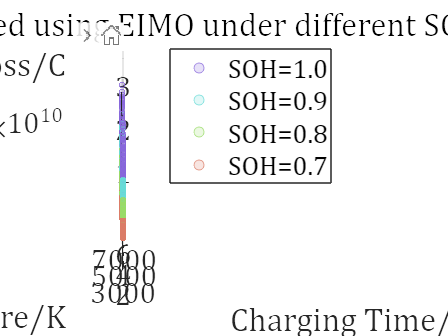

% 绘制整个解集的偏移情况 进行观察
clc;clear;
load("DataSet_Source_ParEGO_1000_100.mat");
x1 = DB.x; y1 = DB.y;
y1 = fun1(y1);
load("DataSet_Source_ParEGO_1000_90.mat");
x2 = DB.x; y2 = DB.y;
y2 = fun1(y2);
load("DataSet_Source_ParEGO_1000_80.mat");
x3 = DB.x; y3 = DB.y;
y3 = fun1(y3);
load("DataSet_Source_ParEGO_1000_70.mat");
x4 = DB.x; y4 = DB.y;
y4 = fun1(y4);
% 绘制使用ParEGO得到的不同SOH下的解集
c = ['#8767DB';'#67DBD7';'#99DB67';'#DB7C67';'#AAAC4D';'#DAD986'];
close(figure(1));
figure(1);
scatter3(y1(:,1),y1(:,2),y1(:,3)*4608000000*96485*55e-6,10,...
    'MarkerFaceColor',c(1,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(1,:),'MarkerEdgeAlpha',0.8)
hold on;
scatter3(y2(:,1),y2(:,2),y2(:,3)*4608000000*96485*55e-6,10,...
    'MarkerFaceColor',c(2,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(2,:),'MarkerEdgeAlpha',0.8)
scatter3(y3(:,1),y3(:,2),y3(:,3)*4608000000*96485*55e-6,10,...
    'MarkerFaceColor',c(3,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(3,:),'MarkerEdgeAlpha',0.8)
scatter3(y4(:,1),y4(:,2),y4(:,3)*4608000000*96485*55e-6,10,...
    'MarkerFaceColor',c(4,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(4,:),'MarkerEdgeAlpha',0.8)
xlabel('Charging Time/s');ylabel('Temperature/K');zlabel('Lithium-ion loss/C');
legend('SOH=1.0','SOH=0.9','SOH=0.8','SOH=0.7');
title("Solutions obtained using EIMO under different SOH");
set(gca,'fontname','Cambria','fontsize',18);

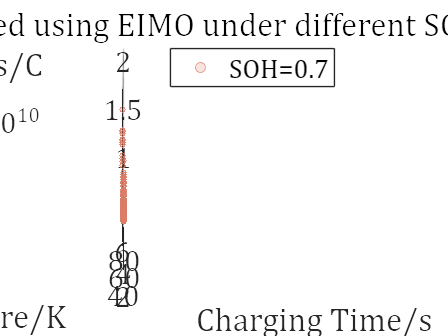

% 绘制整个解集的偏移情况 进行观察
clc;clear;
load("DataSet_Source_ParEGO_1000_70.mat");
x4 = DB.x; y4 = DB.y;
y4 = fun1(y4);
% 绘制使用ParEGO得到的不同SOH下的解集
c = ['#8767DB';'#67DBD7';'#99DB67';'#DB7C67';'#AAAC4D';'#DAD986'];
close(figure(1));
figure(1);
scatter3(y4(:,1),y4(:,2),y4(:,3)*4608000000*96485*55e-6,10,...
    'MarkerFaceColor',c(4,:),'MarkerFaceAlpha',0.2,...
    'MarkerEdgeColor',c(4,:),'MarkerEdgeAlpha',0.8)
xlabel('Charging Time/s');ylabel('Temperature/K');zlabel('Lithium-ion loss/C');
legend('SOH=0.7');
title("Solutions obtained using EIMO under different SOH");
set(gca,'fontname','Cambria','fontsize',18);